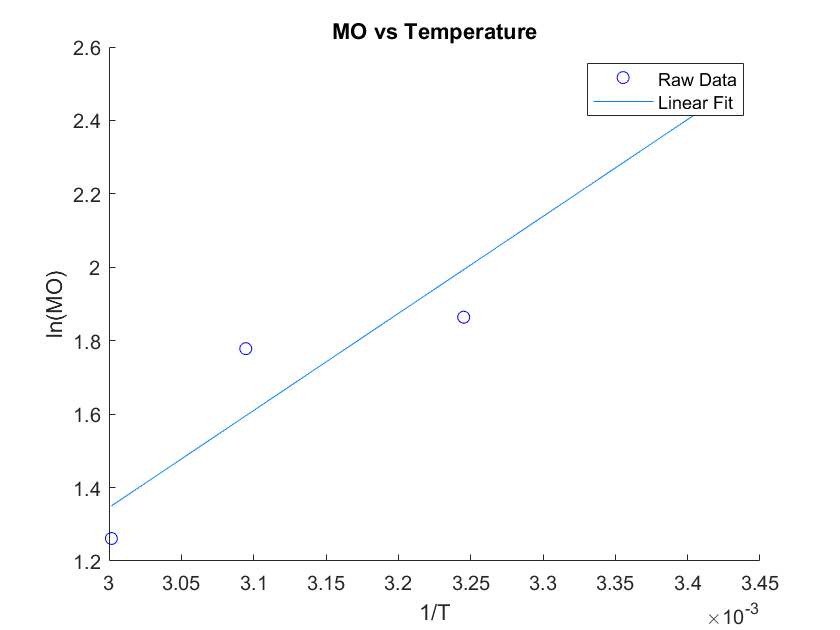

clear
clc
close all
set(0, 'DefaultAxesColorOrder',jet(8));
set(0, 'defaultfigurecolor',[1,1,1]);
%% Part A - Develop the relation for moisture diffusion as a function of temperature, moisture, and porosity
%% Develop GAB Eq with Mo, C, and K as a f(x) of Temperature
%% Plots
Temp = [20, 35, 50, 60]+273.15;
Mo = [11.8, 6.45, 5.92, 3.53];
K = [0.65, 0.71, 0.72, 0.76];
C = [4.21, 8.77, 10.01];
R = 8.314; %universal gas constant J/mol*K
figure()
hold on
scatter(1./Temp, log(Mo),'DisplayName','Raw Data');
X = [1./Temp;ones(1,length(1./Temp))];
linear_coef_mo = polyfit((1./Temp), (log(Mo)), 1);
plot(1./Temp, linear_coef_mo(2) + linear_coef_mo(1).*(1./Temp),'DisplayName','Linear Fit')
legend('show');
title('MO vs Temperature')
xlabel('1/T');
ylabel('ln(MO)');

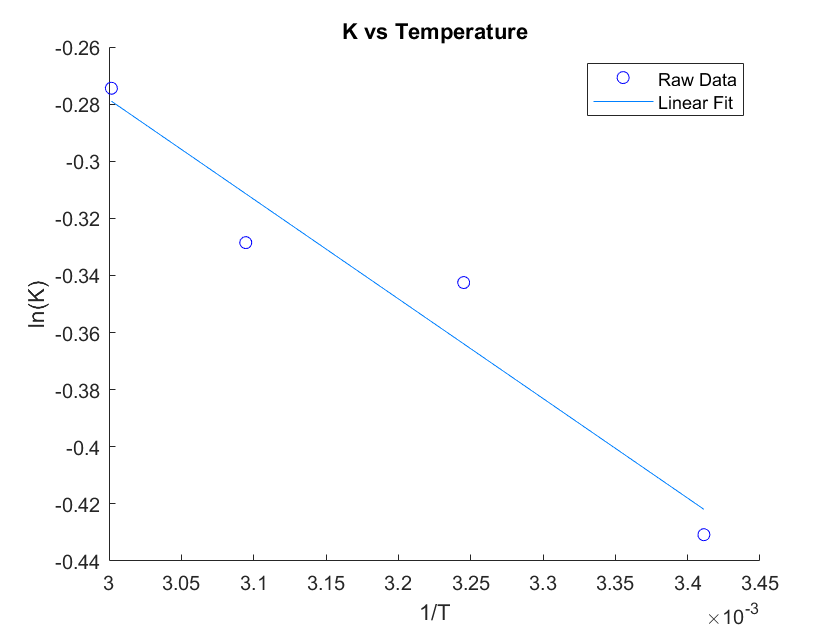

figure()
hold on
scatter(1./Temp, log(K),'DisplayName','Raw Data');
X = [1./Temp;ones(1,length(1./Temp))];
linear_coef_K = polyfit((1./Temp), (log(K)),1);
plot(1./Temp, linear_coef_K(2) + linear_coef_K(1).*(1./Temp),'DisplayName','Linear Fit')
legend('show');
title('K vs Temperature')
xlabel('1/T');
ylabel('ln(K)');

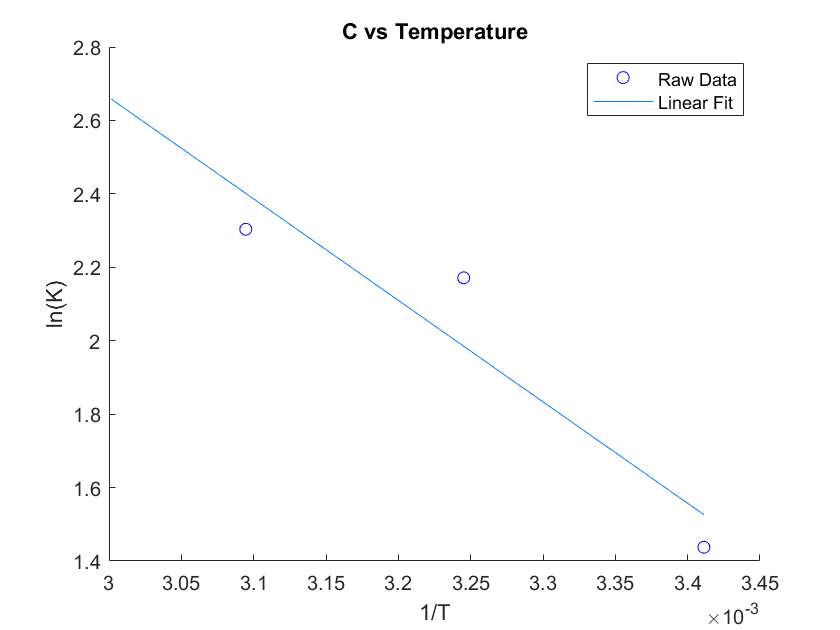

figure()
hold on
scatter(1./Temp(1:3), log(C),'DisplayName','Raw Data');
X = [1./Temp;ones(1,length(1./Temp))];
linear_coef_C = polyfit((1./Temp(1:3)), (log(C)),1);
plot(1./Temp, linear_coef_C(2) + linear_coef_C(1).*(1./Temp),'DisplayName','Linear Fit')
legend('show');
title('C vs Temperature')
xlabel('1/T');
ylabel('ln(K)');

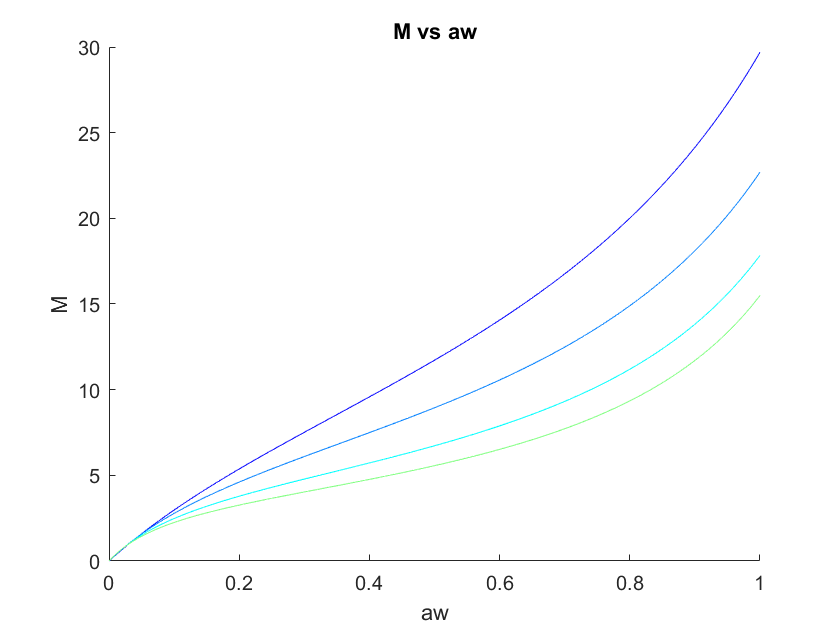

%% GAB Equation
step = 0.00001;
aw = 0:step:1;
M_major = [];
figure(4)
hold on
for i = 1:length(Temp)
    Mo_new = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Temp(i));
    C_new = exp(linear_coef_C(2))*exp(linear_coef_C(1)/Temp(i));
    K_new = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Temp(i));
    for j = 1:length(aw)
        M(j) = (Mo_new*C_new*K_new*aw(j))/((1-K_new*aw(j))*(1+(C_new-1)*K_new*aw(j)));
        M_major(i,j) = M(j);
    end
    % scatter(aw,M)
    plot(aw,M)
end
title('M vs aw')
xlabel('aw');
ylabel('M');

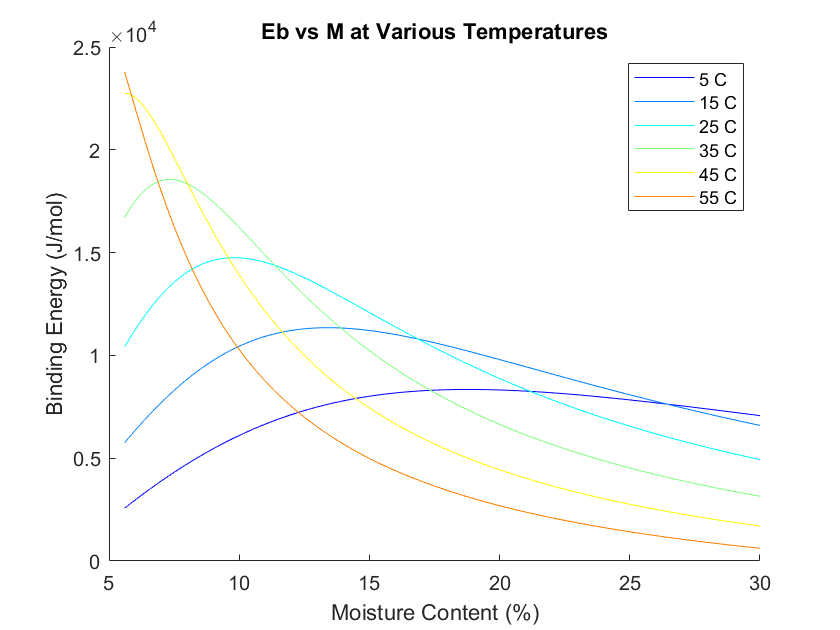

%% Task 2: Determine Eb as f(x) of M and Temperature. Plot Eb vs M @ different Temperatures
Temperature = (5+273.15):(56+273.15);
M_test = 5.6:0.1:30;
aw_isotherm = [];
Eb_major = [];
for i = 1:length(M_test)
    for j = 1:length(Temperature)
        Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Temperature(j));
        C_temp = exp(linear_coef_C(2))*exp(linear_coef_C(1)/Temperature(j));
        K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Temperature(j));
        aw_isotherm(i,j) = (2 + ((Mo_temp/M_test(i))-1)*C_temp - ((2+(Mo_temp/M_test(i)-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
    end
end
for i = 1:length(M_test)
    for j = 1:length(Temperature)-1
        Eb(j) = log(aw_isotherm(i,j+1)/aw_isotherm(i,j))*R/((1/Temperature(j)) - (1/Temperature(j+1)));
        Eb_major(i,j) = Eb(j);
    end
end
figure()
hold on
plot(M_test,Eb_major(:,1))
plot(M_test,Eb_major(:,11))
plot(M_test,Eb_major(:,21))
plot(M_test,Eb_major(:,31))
plot(M_test,Eb_major(:,41))
plot(M_test,Eb_major(:,51))
title('Eb vs M at Various Temperatures')
xlabel('Moisture Content (%)');
ylabel('Binding Energy (J/mol)')
legend('5 C','15 C','25 C','35 C','45 C', '55 C')

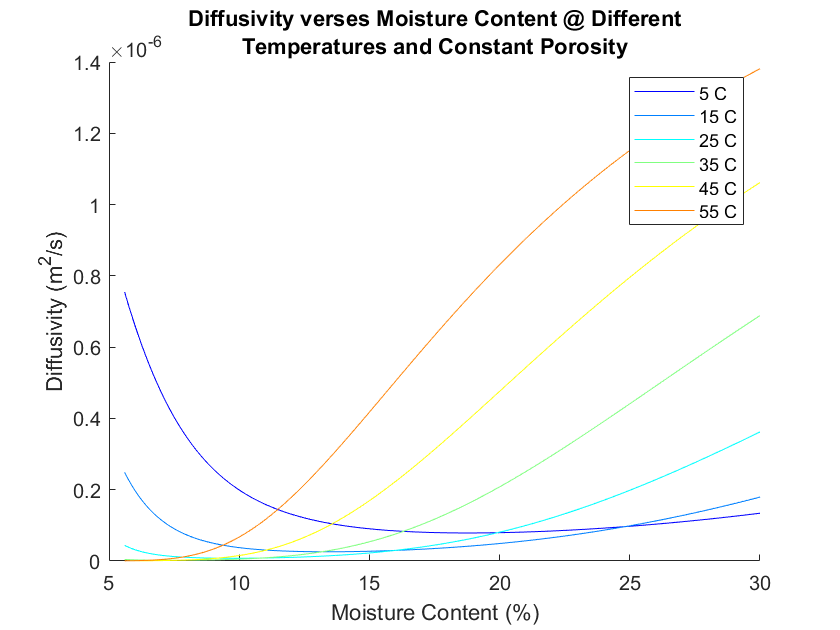

%% Task 3: Determine Deff
%% Determine Deff Vs M at different temperatures (constant porosity)
porosity = 0.5;
tau = 1.5;
phi = 0.5;
Davo = 2*10^-5;
Dalo = 1*10^-9;
Ea = 5.2*4.184;
K = 0.9;
for i = 1:length(M_test)
    for j = 1:length(Temperature)-1
        DAVeff(i,j) = Davo*(exp(-Ea/(R*Temperature(j))))*(K*(exp(-Eb_major(i,j)/(R*Temperature(j)))))/(1 + (K*exp(-Eb_major(i,j)/(R*Temperature(j)))));
        DALeff(i,j) = (Dalo*exp(-Ea/(R*Temperature(j))))*(K*exp(-Eb_major(i,j)/(R*Temperature(j))))/(1 + (K*exp(-Eb_major(i,j)/(R*Temperature(j)))));
        Dserieseff(i,j) = (porosity/tau)*DAVeff(i,j) + ((1-porosity)/tau)*DALeff(i,j);
        Dperpeff(i,j) = ((1/((porosity/tau)*DAVeff(i,j))) + (1/(((1-porosity)/tau)*DALeff(i,j))))^-1;
        Deff(i,j) = phi*Dserieseff(i,j) + (1-phi)*Dperpeff(i,j);
    end
end
figure()
hold on
plot(M_test,Deff(:,1),M_test,Deff(:,11),M_test,Deff(:,21),M_test,Deff(:,31),M_test,Deff(:,41),M_test,Deff(:,51))
title({'Diffusivity verses Moisture Content @ Different', 'Temperatures and Constant Porosity'})
xlabel('Moisture Content (%)')
ylabel('Diffusivity (m^2/s)')
legend('5 C','15 C','25 C','35 C','45 C', '55 C')

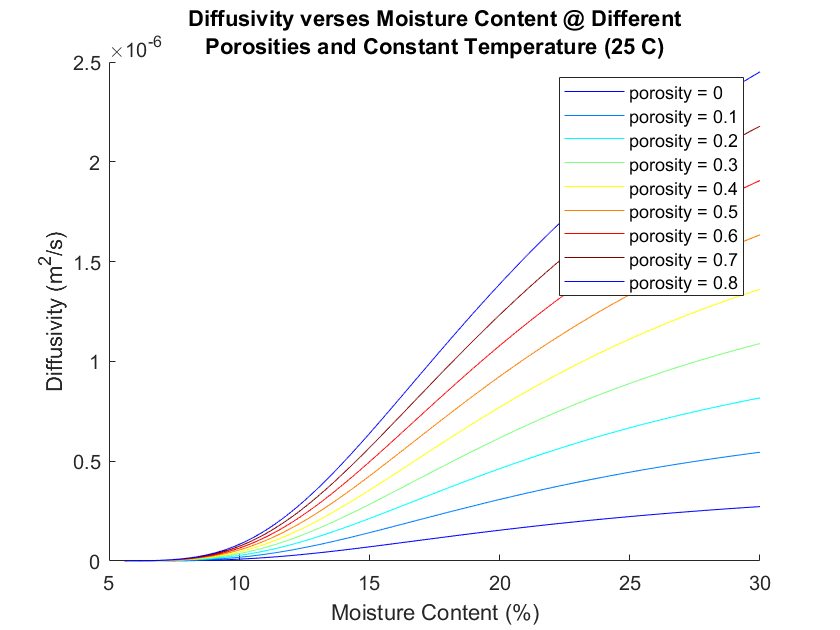

%% Determine Deff vs M at different porosities (constant temperature)
Temp_constant = 25+273.15;
Eb_at_temp_const = Eb_major(:,51).';
porosities = 0.1:0.1:0.9;
for i = 1:length(M_test)
    for j = 1:length(porosities)
        p_DAVeff(i,j) = Davo*exp(-Ea/(R*Temp_constant))*((K*exp(-Eb_at_temp_const(i)/(R*Temp_constant)))/(1 + (K*exp(-Eb_at_temp_const(i)/(R*Temp_constant)))));
        p_DALeff(i,j) = (Dalo*exp(-Ea/(R*Temp_constant)))*((K*exp(-Eb_at_temp_const(i)/(R*Temp_constant)))/(1 + (K*exp(-Eb_at_temp_const(i)/(R*Temp_constant)))));
        p_Dserieseff(i,j) = (porosities(j)/tau)*p_DAVeff(i,j) + ((1-porosities(j))/tau)*p_DALeff(i,j);
        p_Dperpeff(i,j) = ((1/((porosities(j)/tau)*p_DAVeff(i,j))) + (1/(((1-porosities(j))/tau)*p_DALeff(i,j))))^-1;
        p_Deff(i,j) = phi*p_Dserieseff(i,j) + (1-phi)*p_Dperpeff(i,j);
    end
end
figure()
hold on
plot(M_test,p_Deff(:,1),M_test,p_Deff(:,2),M_test,p_Deff(:,3),M_test,p_Deff(:,4),M_test,p_Deff(:,5),M_test,p_Deff(:,6),M_test,p_Deff(:,7),M_test,p_Deff(:,8),M_test,p_Deff(:,9))
%axis([5 15 0.5E-6 5E-6])
title({'Diffusivity verses Moisture Content @ Different', 'Porosities and Constant Temperature (25 C)'})
xlabel('Moisture Content (%)')
ylabel('Diffusivity (m^2/s)')
legend('porosity = 0','porosity = 0.1','porosity = 0.2','porosity = 0.3','porosity = 0.4', 'porosity = 0.5','porosity = 0.6','porosity = 0.7','porosity = 0.8','porosity = 0.9')

%% Part B Determine dryer operating conditions (Temp and HUmidity) maximize shrinkage to dehydrate soy
%% Plot Tg as f(x) of M using FOX equation and determine T and RH for one-stage dryer
Tg_solid = 410; %Kelvin
Tg_water = 134; %Kelvin
M_range = 0:0.001:0.9;
Tman = 150:500;
for i = 1:length(M_range)
    Tg_original(i) = ((M_range(i)/Tg_water) + ((1-M_range(i))/Tg_solid))^-1;
end
Tg_30 = Tg_original + 30;
Tg_10 = Tg_original + 10;
Mc_initial = 0.6;
Mc_desired = 0.1;
Mc_final = 0.6;
Tg_initial = Tg_original;
stages = [1 0.6;0 0];
i = 2;
temp_change = Tg_10(Mc_desired*1000+1) - Tg_10(Mc_initial*1000+1);
Tg_op = Tg_original + temp_change;
Operating_Temperature = Tg_op(Mc_desired*1000+1);
Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Operating_Temperature);
C_temp = exp(linear_coef_C(2))*exp(linear_coef_C(1)/Operating_Temperature);
K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Operating_Temperature);
RH = (2 + ((Mo_temp/10)-1)*C_temp - ((2+(Mo_temp/10-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
RH = RH*100;
fprintf('For a one stage dryer, the operating temperature must be %.2f K and the RH must be %.2f percent \n\n',Operating_Temperature,RH)

For a one stage dryer, the operating temperature must be 496.57 K and the RH must be 90.98 percent 



%% Multi-Stage Dryer
while Mc_final > 0.1
    Op_Temp = Tg_30(Mc_final*1000+1);
    
    Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Op_Temp);
    C_temp = exp(linear_coef_C(2))*exp(linear_coef_C(1)/Op_Temp);
    K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Op_Temp);
    
    Mc_final = round(Tg_water*(Tg_solid - Tg_30(Mc_final*1000+1))/(Tg_30(Mc_final*1000+1)*(Tg_solid - Tg_water)),3);
    stages(i,1) = i;
    stages(i,2) = Mc_final;
    
    RH_stage = (2 + ((Mo_temp/(Mc_final*100))-1)*C_temp - ((2+(Mo_temp/(Mc_final*100)-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
    RH_stage = RH_stage*100;
    
    stages(i-1,3) = RH_stage;
    i = i+1;
end
%% Optimizing Operating Temperature for Multi Stage
op_temp_range = (round(Tg_original(Mc_initial*1000+1),0)+10)+1:0.1:(round(Tg_original(Mc_initial*1000+1),0)+30);
mc_in = [];
mc_out = [];
final_mc_values = [0 0;0 0];
RH_values = [];
stage_op_temps = [];
for i = 1:length(op_temp_range)
    final_mc_values(i,1) = op_temp_range(i);
    Tg_op_temp = Tg_original + (op_temp_range(i)-Tg_original(Mc_initial*1000+1));
    Mc_final = Mc_initial;
    stages_temp = [1 0.6;0 0];
    j = 2;
    while Mc_final > 0.1
        mc_in(i,j) = Mc_final;
        Op_temp_index = Mc_final*1000+1;
        Op_Temp = Tg_op_temp(Op_temp_index);
        stage_op_temps(i,j-1) = Op_Temp;
        Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Op_Temp);
        C_temp = exp(linear_coef_C(2))*exp(linear_coef_C(1)/Op_Temp);
        K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Op_Temp);
        Mc_final = round(Tg_water*(Tg_solid - Op_Temp + 10)/((Op_Temp-10)*(Tg_solid - Tg_water)),3);
        stages_temp(j,1) = j;
        stages_temp(j,2) = Mc_final;
        mc_out(i,j) = Mc_final;
        RH_stage = (2 + ((Mo_temp/(Mc_final*100))-1)*C_temp - ((2+(Mo_temp/(Mc_final*100)-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
        RH_stage = RH_stage*100;
        RH_values(i,j) = round(RH_stage);
        stages_temp(j-1,3) = RH_stage;
        j = j+1;
    end
    final_mc_values(i,2) = stages_temp(length(stages_temp),2);
    final_mc_values(i,3) = j-2;
end
optimal_temp_values(1,:) = op_temp_range(find(final_mc_values(:,2)==0.1));
optimal_temp_values(2,:) = final_mc_values(find(final_mc_values(:,2) == 0.1),3);
optimal_temperature_index = find(op_temp_range == optimal_temp_values(1,length(optimal_temp_values)));
mc_in_final = mc_in(optimal_temperature_index,:);
mc_out_final = mc_out(optimal_temperature_index,:);
optimal_op_temp_values = stage_op_temps(optimal_temperature_index,:);
optimal_RH_values = RH_values(optimal_temperature_index,:);
fprintf('Multi-Stage Dryer Operating Conditions:\n');

Multi-Stage Dryer Operating Conditions:


for i = 1:optimal_temp_values(2,length(optimal_temp_values))
    fprintf('Stage %d Operating Temperature: %.2f K RH: %d percent MC_in = %.2f MC_out = %.2f\n',i,optimal_op_temp_values(i),optimal_RH_values(i+1),mc_in_final(i+1),mc_out_final(i+1));
end

Stage 1 Operating Temperature: 213.00 K RH: 99 percent MC_in = 0.60 MC_out = 0.49
Stage 2 Operating Temperature: 232.64 K RH: 83 percent MC_in = 0.49 MC_out = 0.41
Stage 3 Operating Temperature: 252.16 K RH: 75 percent MC_in = 0.41 MC_out = 0.34
Stage 4 Operating Temperature: 271.64 K RH: 76 percent MC_in = 0.34 MC_out = 0.28
Stage 5 Operating Temperature: 291.37 K RH: 84 percent MC_in = 0.28 MC_out = 0.22
Stage 6 Operating Temperature: 310.97 K RH: 91 percent MC_in = 0.22 MC_out = 0.18
Stage 7 Operating Temperature: 330.54 K RH: 94 percent MC_in = 0.18 MC_out = 0.14
Stage 8 Operating Temperature: 349.90 K RH: 93 percent MC_in = 0.14 MC_out = 0.10


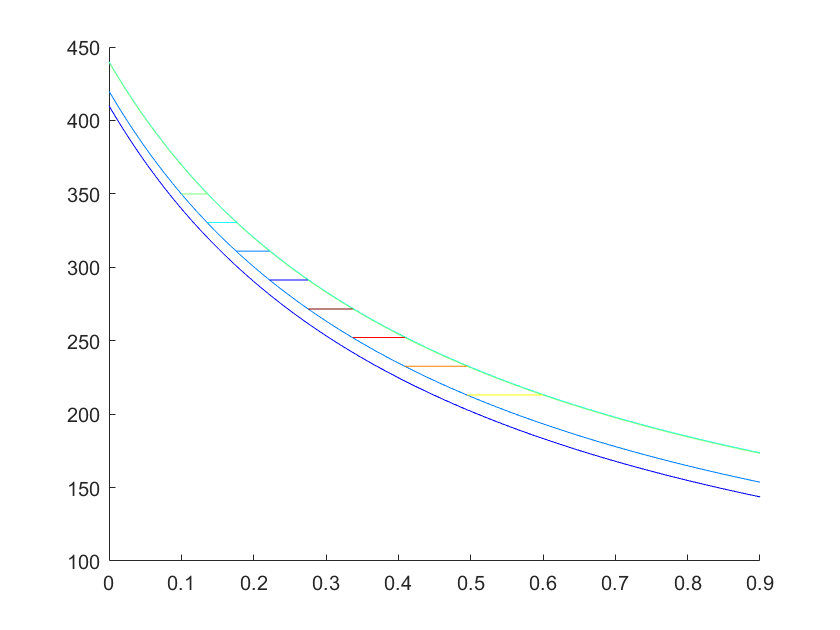

figure()
hold on
plot(M_range,Tg_original,M_range,Tg_original+10,M_range, Tg_original+30,M_range, Tg_original+(optimal_op_temp_values(1)-Tg_original(0.6*1000+1)))
for i = 1:optimal_temp_values(2,length(optimal_temp_values))
    plot([mc_out_final(i+1),mc_in_final(i+1)],[optimal_op_temp_values(i),optimal_op_temp_values(i)
        ])
end